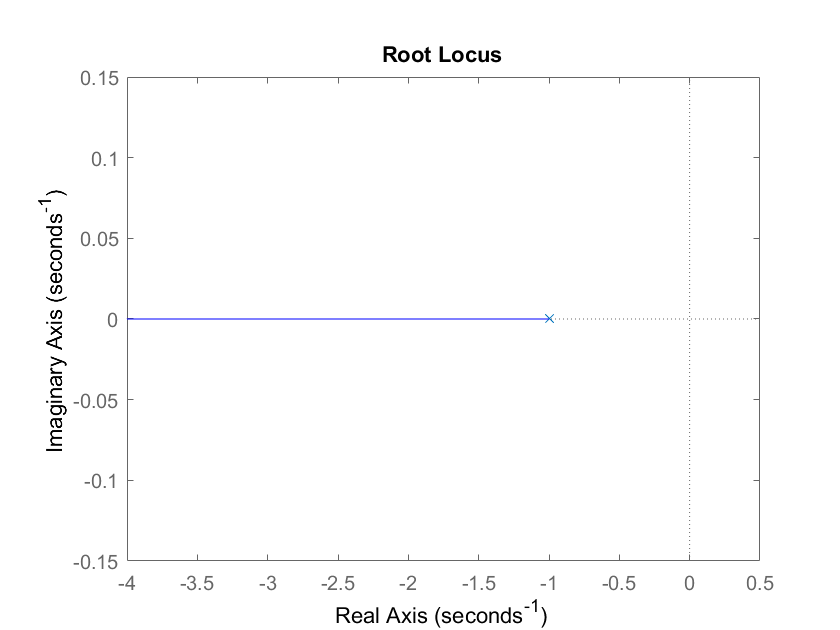

clc
clear
%Q1
plant_up = 1;
plant_down=[1 1];
plant = tf(plant_up,plant_down);
figure(1)
rlocus(plant);

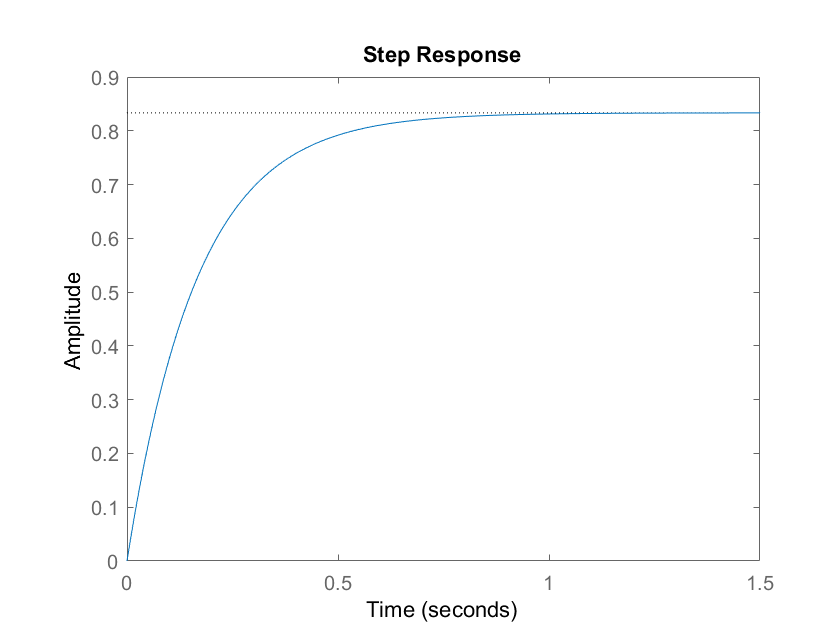

%by rlocus find k= 5
%必迴路轉開迴路才可做後續計算
plant_open = feedback(plant*5,1,-1);
figure(2)
step(plant_open)

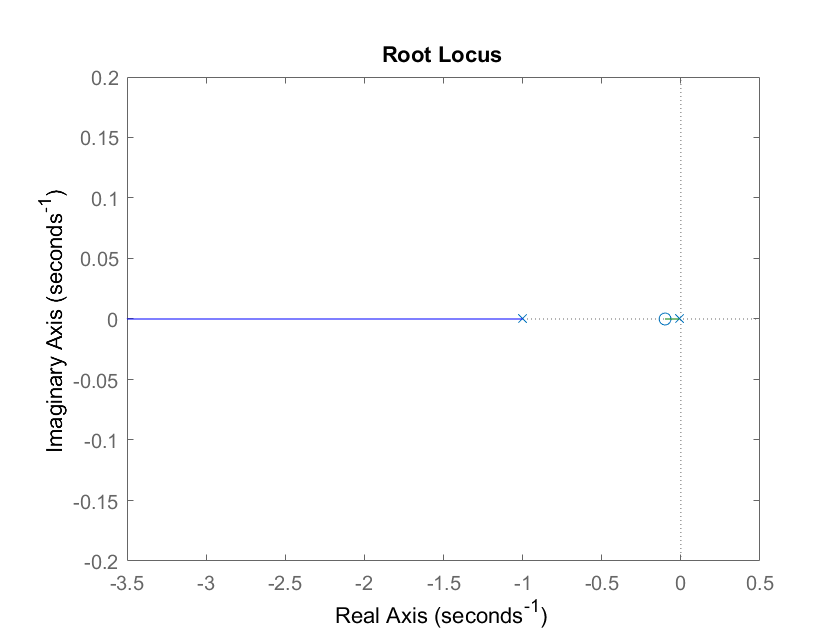

%as the result i can found e = 0.17
syms s t
f = ilaplace(5/(s^2+6*s));
%get y = 5/6 - (5*exp(-6*t))/6
%Q2
%first set z = 0.01-> can't change to 0.1 
plant2 = series(tf([1 0.1],[1 0.01]),plant);
figure(3)
rlocus(plant2);

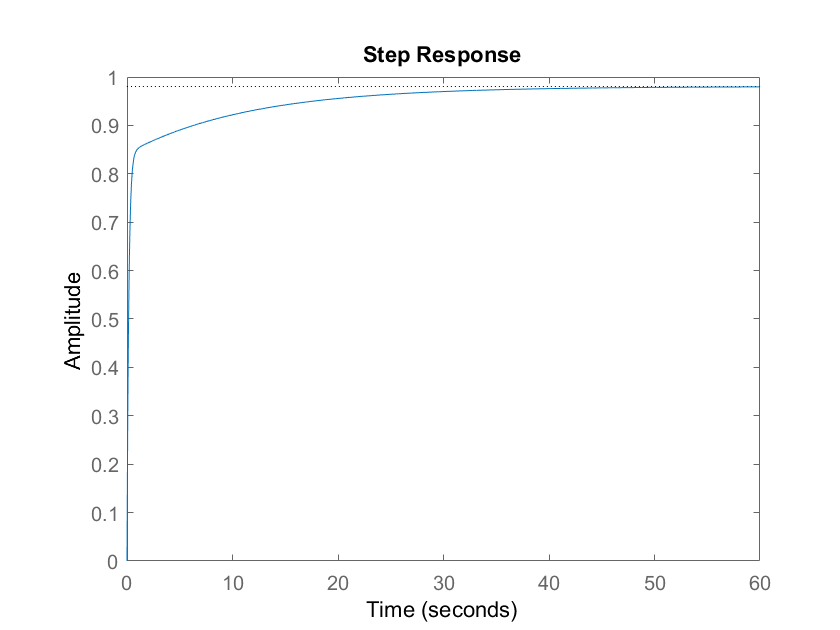

%as it set K=5 s==-6 -> K=5 s==-6
plant2_open = feedback(plant2*5,1,-1);
figure(4)
step(plant2_open)

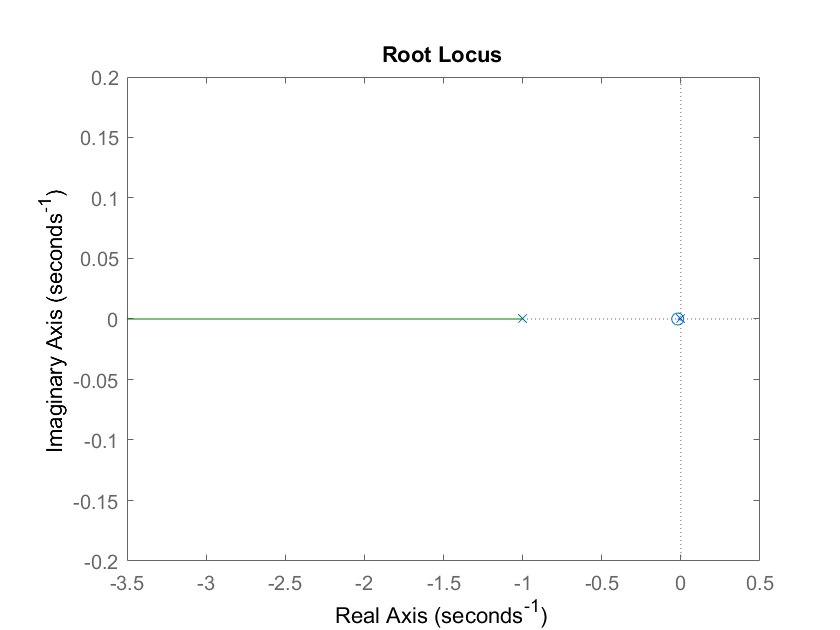

%for z=0.1 p=0.01 k=5 find the answer
%Q3
plant3=series(tf([1 0.02],[1 0]),plant);
figure(5)
rlocus(plant3)

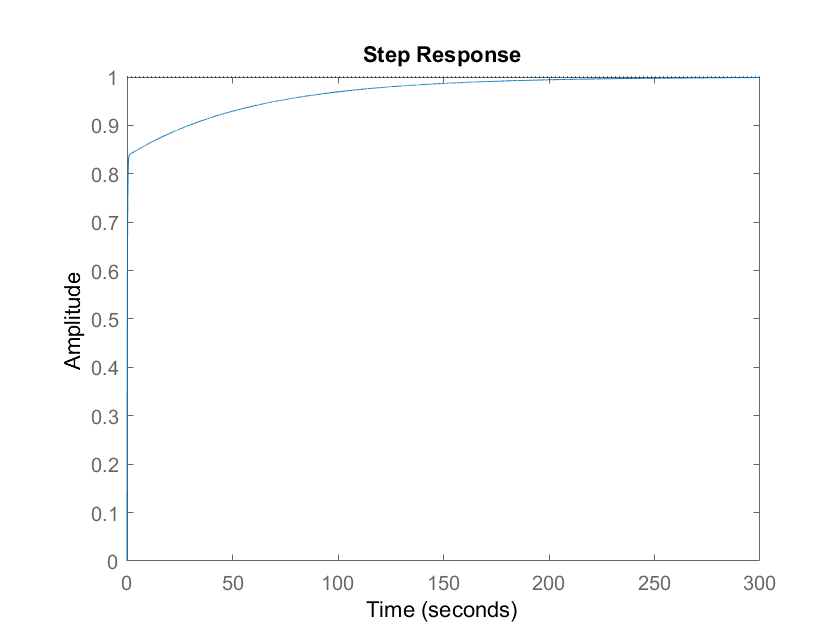

%get s=-6 K=5.05
plant3_open = feedback(plant3*5.05,1,-1);
figure(6)
step(plant3_open);

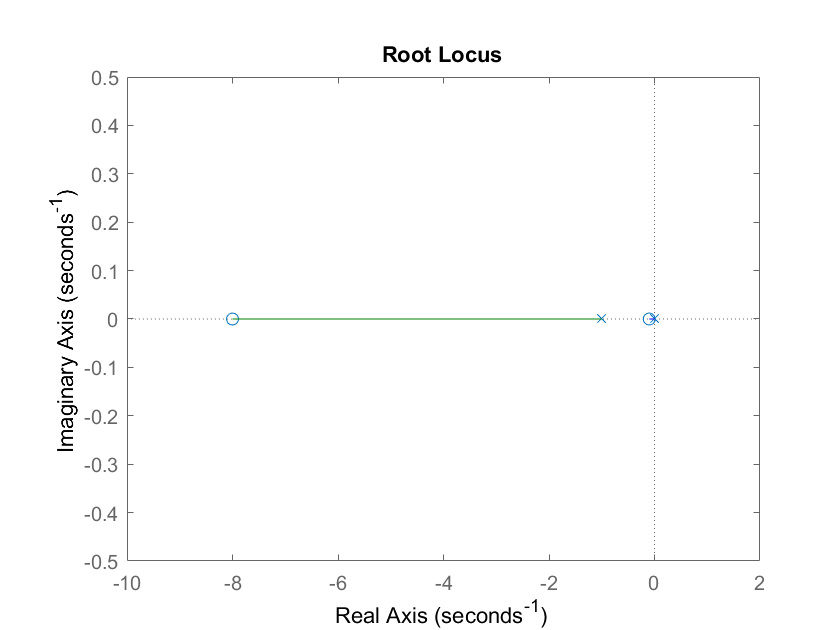

%as it know error is = 0
%Q4 set z1=0.1 z2=8
plant4=series(tf(conv([1 0.1],[1 8]),[1 0]),plant);
figure(6)
rlocus(plant4)

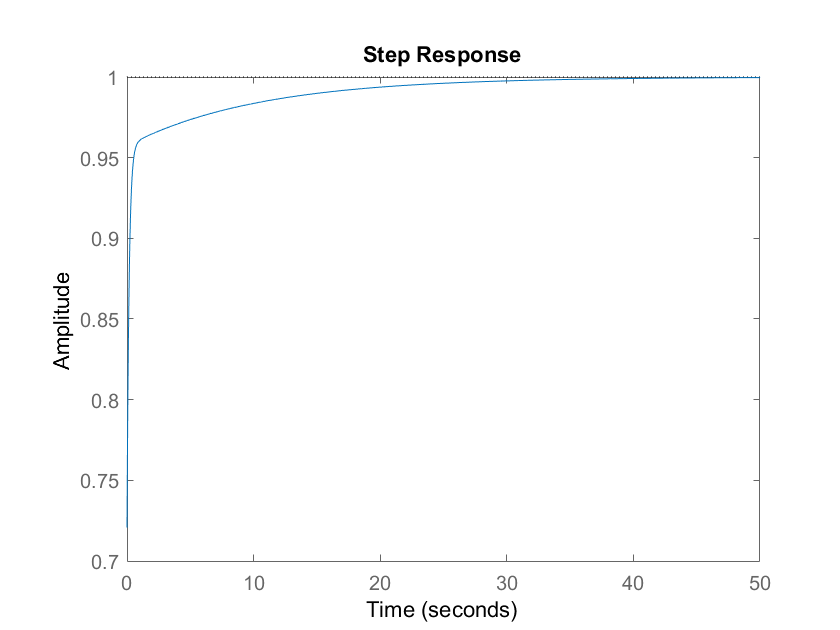

%find whem s= -6 K=2.58
plant4_open = feedback(plant4*2.58,1,-1);
figure(7)
step(plant4_open);

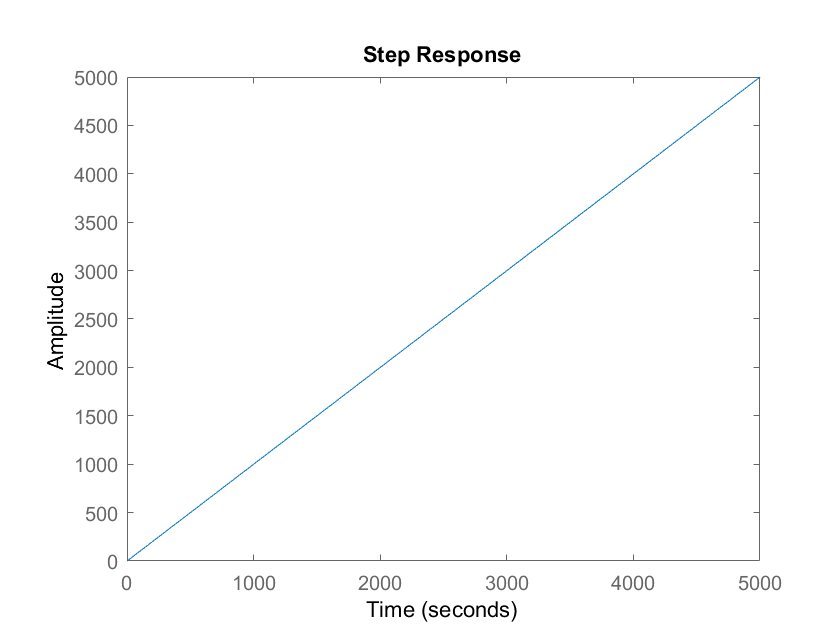

%error step = 0
figure(8)
step(plant4_open*tf(1,[1 0]));

%as it get error for ramp = 0.5;